cd '/Users/djogem/Downloads/2022Spring/COMP 572/HW7'
pwd

%1
close('all');   % close all open figures so we start with a clean slate!

I=im2double(imread('couple.jpg'));

% Get foreground mask (part that stays sharp) from the user

% For the given image, a mask is provided as an image
mask = im2double(imread('mask.png'));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 15;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result1a = method1(I, mask, bokeh_shape);
result1b = method2(I, mask, bokeh_shape);
result1 = method3(I, mask, bokeh_shape);

figure; montage({I, result1a, result1b, result1});

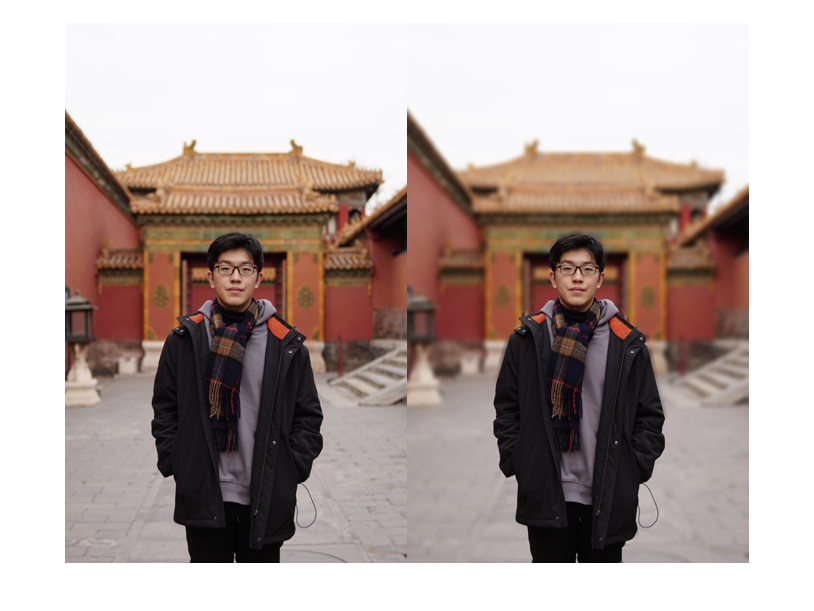

%2
I=im2double(imread('me.jpg'));

% Interactively draw the foreground mask as a polygon

% [poly_x, poly_y] = getPolygonForMask(I);
% disp("Copy the values of the vectors poly_x and poly_y from the " + ...
%     "Command Window below and hard code them inside your code for " + ...
%     "submission via the Grader website.");
% poly_x        % display x coords of polygon
% poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [323.5160  228.7925  309.7792  390.7659  426.7600  399.7644  404.2637  399.7644  431.2592  471.7526  521.2445  557.2385  566.2371  557.2385  579.7348  678.7186  737.2090  746.2075  705.7141  728.2104  701.2149  656.2223  615.7289  323.2770];
poly_y = [1543.7    1118.6    844.1    785.6  776.6    731.6    704.6    659.6    619.1    605.7    605.7    632.6    700.1    754.1    785.6    893.6 1132.1   1217.5    1316.5    1406.5    1456.0    1451.5    1537.0    1546.0];
mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 10;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result2 = method3(I, mask, bokeh_shape);

figure; montage({I, result2});

%3
I=im2double(imread('fednadal.jpeg'));

% Interactively draw the foreground mask as a polygon

% [poly_x, poly_y] = getPolygonForMask(I);
% disp("Copy the values of the vectors poly_x and poly_y from the " + ...
%     "Command Window below and hard code them inside your code for " + ...
%     "submission via the Grader website.");
% poly_x = [786.5 889.7 957.6 1019.5 1090.3 1010.6 1001.8 1122.7 771.7 816.0 730.5 718.7 689.2 736.4 783.5]       % display x coords of polygon
% poly_y = [127.5046  103.9101  139.3018  263.1728  292.6659  342.8041  431.2834  552.2051  717.3664  720.3157  510.9147  443.0806  378.1959  351.6521  165.8456  121.6060]      % display y coords of polygon
% % Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [786.5 889.7 957.6 1019.5 1090.3 1010.6 1001.8 1110.9 1122.7 771.7 816.0 730.5 718.7 689.2 736.4 783.5]       % display x coords of polygon
poly_y = [127.5046  103.9101  139.3018  263.1728  292.6659  342.8041  431.2834  552.2051  717.3664  720.3157  510.9147  443.0806  378.1959  351.6521  165.8456  121.6060]      % display y coords of polygon


mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 15;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result3 = method3(I, mask, bokeh_shape);

figure; montage({I, result3});

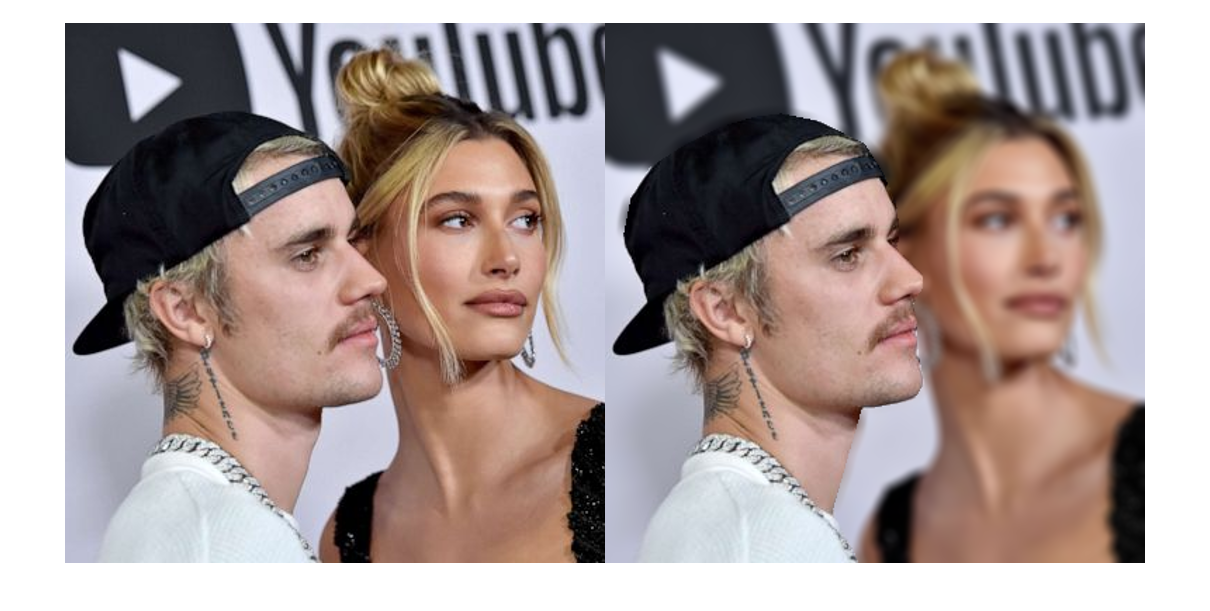

%4
I=im2double(imread('bieber.jpeg'));


% Interactively draw the foreground mask as a polygon

% [poly_x, poly_y] = getPolygonForMask(I);
% disp("Copy the values of the vectors poly_x and poly_y from the " + ...
%     "Command Window below and hard code them inside your code for " + ...
%     "submission via the Grader website.");

% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [16.1735   58.5207   38.3397   -2.0222   24.7458   12.4130   19.1400   32.5940   57.2596   80.8041  106.5909  125.6507  153.6798  185.0725  198.5265  207.4958  209.7381  208.6170  226.5556  226.5556  219.8286  222.0709  222.0709  223.1921  227.6768  219.8286  182.8302  162.6492  181.7090];    
poly_y = [385.0598  282.4731  246.5958  243.2323  189.4164  156.9026  124.3888  103.0866   87.3903   75.0575   67.2093   64.9670   70.5728   86.2692  107.5713  127.7523  144.5698  161.3872  179.3259  188.2952  200.6280  210.7185  220.8090  234.2630  256.6863  269.0191  275.7461  346.3796  385.6203];      
mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 5;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result4 = method3(I, mask, bokeh_shape);

figure; montage({I, result4});

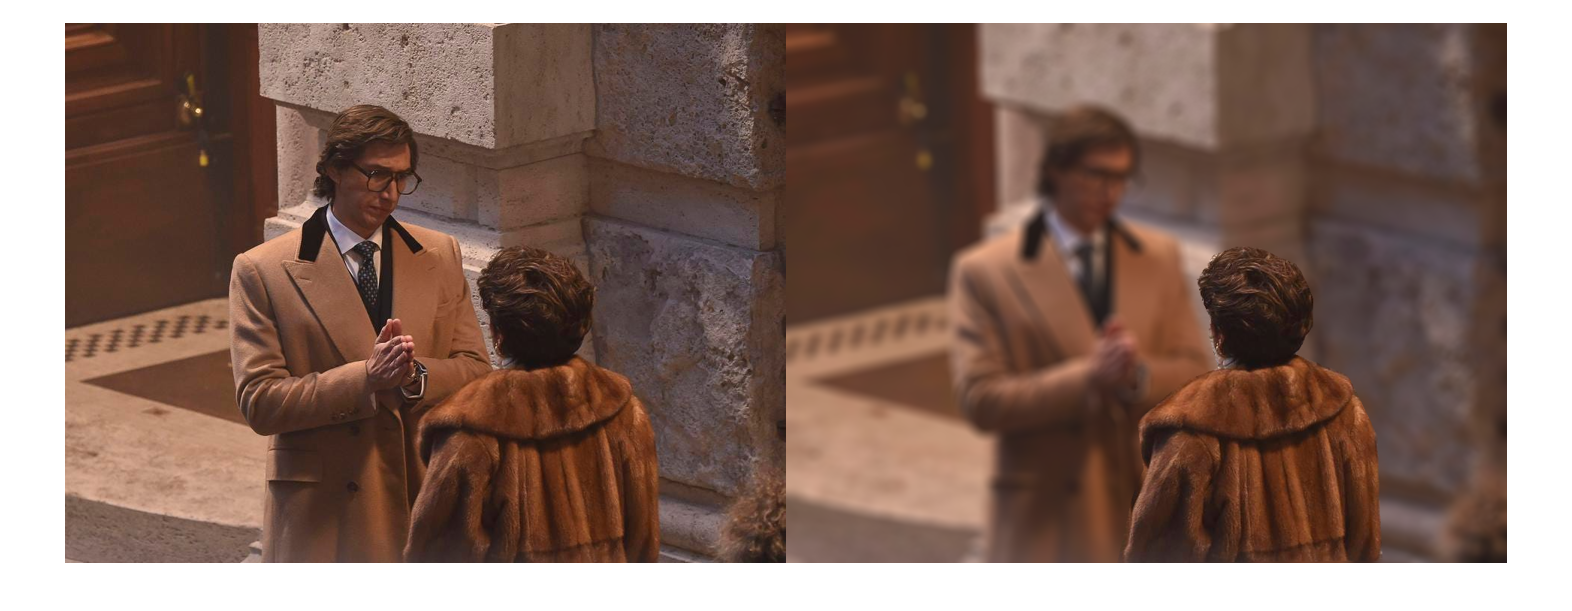

%5
I=im2double(imread('gucci.jpeg'));

% Interactively draw the foreground mask as a polygon

% [poly_x, poly_y] = getPolygonForMask(I);
% disp("Copy the values of the vectors poly_x and poly_y from the " + ...
%     "Command Window below and hard code them inside your code for " + ...
%     "submission via the Grader website.");
% poly_x        % display x coords of polygon
% poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [441.3306  461.2177  476.6855  467.8468  529.7177  576.1210  562.8629  565.0726  554.0242  547.3952  569.4919  600.4274  629.1532  655.6694  682.1855  695.4435  702.0726  702.0726  679.9758  748.4758  761.7339  788.2500  790.4597  794.8790] ;
poly_y = [720.1774  632.1290  594.5645  530.4839  477.4516  459.7742  415.5806  393.4839  369.1774  342.6613  309.5161  298.4677  298.4677  311.7258  322.7742  349.2903  366.9677  404.5323  442.0968  468.6129  495.1290  550.3710  625.5000  716.0968];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 10;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result5 = method3(I, mask, bokeh_shape);

figure; montage({I, result5});

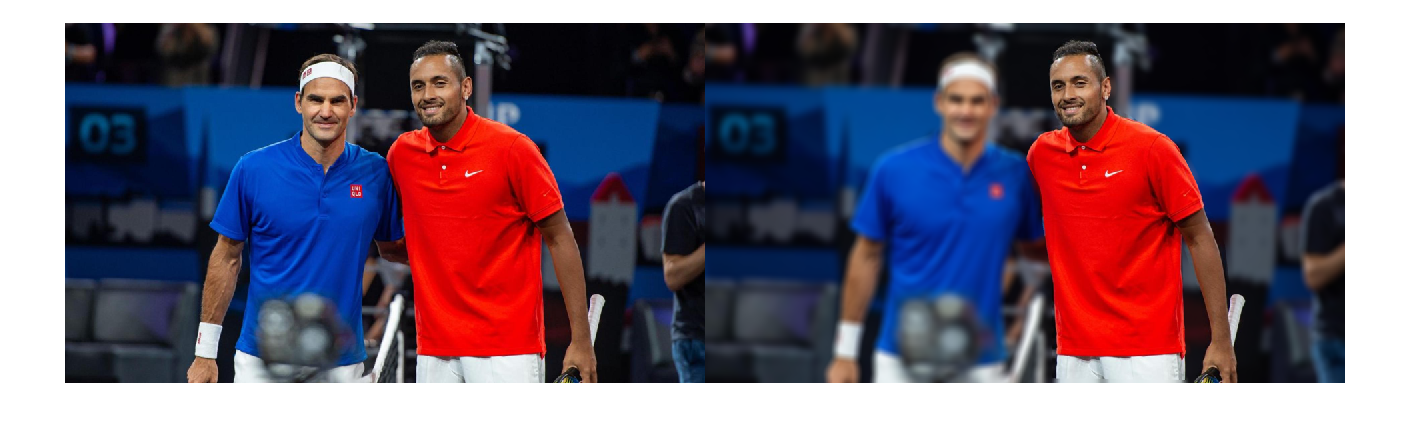

poly_x =           1042.34331797235          1042.34331797235          1011.37557603687          1002.52764976959           962.71198156682          984.831797235023          1064.46313364055          1033.49539170507          1029.07142857143           1091.0069124424            1157.366359447          1179.48617511521          1210.45391705069          1219.30184331797          1210.45391705069           1298.9331797235          1409.53225806452          1515.70737327189          1559.94700460829          1577.64285714286           1626.3064516129          1621.88248847926          1599.76267281106           1604.1866359447          1467.04377880184          1502.43548387097          1484.73963133641          1431.65207373272          1444.92396313364


poly_y =           1066.95161290323           779.39400921659          593.587557603687          491.836405529954          412.205069124424          332.573732718894          306.029953917051          239.670506912442          89.2557603686635          36.1682027649767           45.016129032258          75.9838709677418          151.191244239631          195.430875576037          244.094470046083          292.758064516129          345.845622119816          562.619815668203          664.370967741936          814.785714285714          814.785714285714          876.721198156682          974.048387096774          1080.22350230415          1080.22350230415          965.200460829493          810.361751152074          659.947004608295          1071.37557603687


%6
I=im2double(imread('kyrgios.jpeg'));

% Interactively draw the foreground mask as a polygon

% [poly_x, poly_y] = getPolygonForMask(I);
% disp("Copy the values of the vectors poly_x and poly_y from the " + ...
%     "Command Window below and hard code them inside your code for " + ...
%     "submission via the Grader website.");
% poly_x        % display x coords of polygon
% poly_y        % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.
poly_x = [1042.34331797235          1042.34331797235          1011.37557603687          1002.52764976959           962.71198156682          984.831797235023          1064.46313364055          1033.49539170507          1029.07142857143           1091.0069124424            1157.366359447          1179.48617511521          1210.45391705069          1219.30184331797          1210.45391705069           1298.9331797235          1409.53225806452          1515.70737327189          1559.94700460829          1577.64285714286           1626.3064516129          1621.88248847926          1599.76267281106           1604.1866359447          1467.04377880184          1502.43548387097          1484.73963133641          1431.65207373272          1444.92396313364];
poly_y = [1066.95161290323           779.39400921659          593.587557603687          491.836405529954          412.205069124424          332.573732718894          306.029953917051          239.670506912442          89.2557603686635          36.1682027649767           45.016129032258          75.9838709677418          151.191244239631          195.430875576037          244.094470046083          292.758064516129          345.845622119816          562.619815668203          664.370967741936          814.785714285714          814.785714285714          876.721198156682          974.048387096774          1080.22350230415          1080.22350230415          965.200460829493          810.361751152074          659.947004608295          1071.37557603687];

mask = poly2mask(poly_x, poly_y, size(I, 1), size(I, 2));

% Define the bokeh filter shape
% A simple disk filter is provided as default
% For extra credit you may optionally define a different shape, e.g., hexagon, starburst, heart etc.

radius = 15;            % choose this carefully for each image
bokeh_shape = fspecial('disk', radius);

result6 = method3(I, mask, bokeh_shape);

figure; montage({I, result6});

function result = method1(I, mask, filter)
    I_blur = imfilter(I, filter, 'replicate');
    result = I_blur .* (1 - mask) + I .* mask;
end

function result = method2(I, mask, filter)
    bg = I .* (1 - mask);
    bg_blur = imfilter(bg, filter, 'replicate');
    result = bg_blur .* (1 - mask) + I .* mask;
end

function result = method3(I, mask, filter) 
    % YOUR CODE HERE
    bg = I .* (1 - mask);
    numerator = imfilter(bg, filter, 'replicate');
    
    denominator = imfilter((1-mask), filter, 'replicate');
    bg_blur = numerator ./ denominator;
    bg_blur(isnan(bg_blur)) = 0;
    result = bg_blur .* (1 - mask) + I .* mask;
    
end

function [poly_x, poly_y] = getPolygonForMask(im)
    % Asks user to draw polygon around input image.  
    disp('Draw polygon around source object in clockwise order, q to stop');
    fig=figure; hold off; imagesc(im); axis image;
    poly_x = [];
    poly_y = [];
    while 1
        figure(fig)
        [x, y, b] = ginput(1);
        if b=='q'
            break;
        end
        poly_x(end+1) = x;
        poly_y(end+1) = y;
        hold on; plot(poly_x, poly_y, '*-');
    end
    close(fig);
end